clear all;
close all;
clc;


## Generacion de señales artificiales con operaciones,funciones

f0 = [31, 59, 89, 127, 191, 223, 257]; % Vector de frecuencias
fs = 4*max(f0); % frecuencia de muestreo
tad = 10;
ts=1/fs;
t=0:ts:tad-ts;
w0 = 2*pi*f0;
sx=0;
sx2=0;
sx3=0;

## señal1

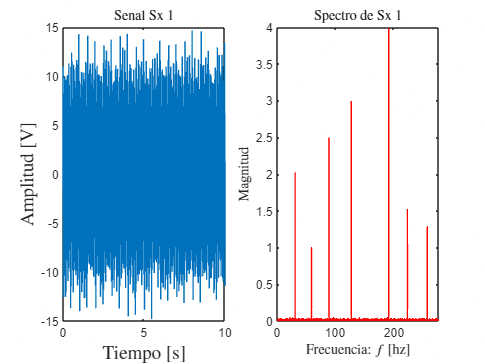

%señal
sx = sx+(2*sin(w0(:,1).*t)+1*sin(w0(:,2).*t)+2.5*sin(w0(:,3).*t)...
            +3*sin(w0(:,4).*t)+4*sin(w0(:,5).*t)+1.5*sin(w0(:,6).*t)...
            +1.3*sin(w0(:,7).*t));
sx=awgn(sx,2);
%fourier
[tfsx, fsx] = tfourier(sx,fs);

%grafica señal 1
figure;
subplot(1,2,1)
plot(t,sx);
title(sprintf('Senal Sx 1'),"FontSize",10,'FontWeight',"bold","Interpreter","latex")
xlabel('Tiempo [s]', 'FontSize', 14, "FontWeight", "bold", "Interpreter", "latex");
ylabel('Amplitud [V]', 'FontSize', 14, "FontWeight", "bold", "Interpreter", "latex");
subplot(1,2,2)
set(gcf, 'Color', 'w');
plot(fsx, tfsx, 'r', 'LineWidth', 1.0);
title(sprintf('Spectro de Sx 1'),"FontSize",10,'FontWeight',"bold","Interpreter","latex")
xlabel('Frecuencia: $ f $ [hz]', 'FontSize', 10, 'FontWeight', 'bold', 'Interpreter', 'LaTex');
ylabel('Magnitud', 'FontSize', 10, 'FontWeight', 'bold', 'Interpreter', 'LaTex');
xlim([0 max(f0)+20]);


% identificacion de señal y artefacto
%señal
[pks11, locs11]=findpeaks1(tfsx,[1.95 2.05],[0.95 1.05],[2.95 3.05],[3.95 4.05]);
%Artefactos
[pks12, locs12]=findpeaks(tfsx,[2.45 2.55],[1.45 1.55],[1.25 1.35]);

%grafica de identificacion de señal y artefacto
figure;
subplot(1,2,1);
plot(fsx,tfsx);
hold on
plot(fsx(locs12),pks12,'*r');
plot(fsx(locs11),pks11,'ob');
title(" Spectro de Sx 1");
xlabel("Frecuencia [Hz]");
ylabel("Amplitud");
xlim([0 max(f0)+20]);

%Filtrado
tic
[sxbut, time11]=fbutt(sx,[73 99],fs,"stop",6);
toc

Elapsed time is 0.040192 seconds.


tic
[sxbut, time12]=fbutt(sxbut,[210 265],fs,"stop",7);
toc

Elapsed time is 0.013218 seconds.


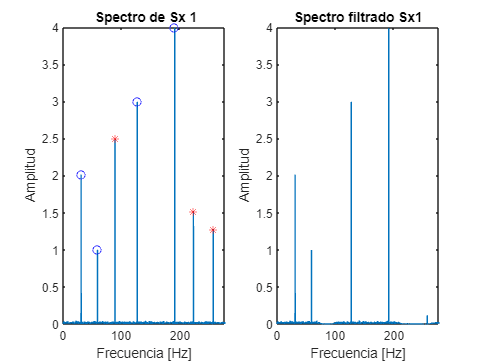

[fsx, tsxbut]=fourier(sxbut,fs);

%grafica
subplot(1,2,2);
plot(fsx, tsxbut);
title("Spectro filtrado Sx1");
xlabel("Frecuencia [Hz]");
ylabel("Amplitud");
xlim([0 max(f0)+20]);


% caracterizacion para señal low
valor_maximo =max(tsxbut) % valor maximo

valor_maximo = 3.9836

valor_promedio = mean(tsxbut) % valor promedio

valor_promedio = 0.0141

desviacion_stadar = std(tsxbut) % desviacion estandar

desviacion_stadar = 0.0763

varianza = var(tsxbut) % varianza de la señal

varianza = 0.0058

correlacion=corrcoef([sx;sxbut]')

correlacion =     1.0000    0.0829
    0.0829    1.0000


## señal 2

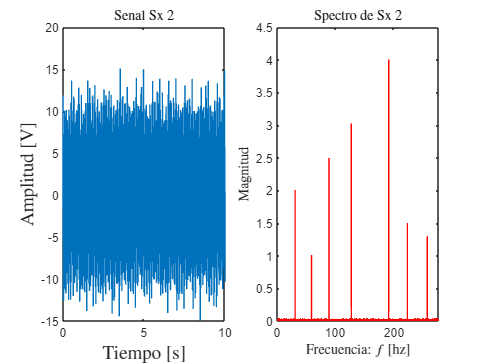

%señal
sx2 = sx2+(2*sin(w0(:,1).*t)+1*sin(w0(:,2).*t)+2.5*sin(w0(:,3).*t)...
            +3*sin(w0(:,4).*t)+4*sin(w0(:,5).*t)+1.5*sin(w0(:,6).*t)...
            +1.3*sin(w0(:,7).*t));
sx2=awgn(sx2,2);
%fourier
[tfsx2, fsx2] = tfourier(sx2,fs);

%grafica señal 2
figure;
subplot(1,2,1)
plot(t,sx2);
title(sprintf('Senal Sx 2'),"FontSize",10,'FontWeight',"bold","Interpreter","latex")
xlabel('Tiempo [s]', 'FontSize', 14, "FontWeight", "bold", "Interpreter", "latex");
ylabel('Amplitud [V]', 'FontSize', 14, "FontWeight", "bold", "Interpreter", "latex");
subplot(1,2,2)
set(gcf, 'Color', 'w');
plot(fsx2, tfsx2, 'r', 'LineWidth', 1.0);
title(sprintf('Spectro de Sx 2'),"FontSize",10,'FontWeight',"bold","Interpreter","latex")
xlabel('Frecuencia: $ f $ [hz]', 'FontSize', 10, 'FontWeight', 'bold', 'Interpreter', 'LaTex');
ylabel('Magnitud', 'FontSize', 10, 'FontWeight', 'bold', 'Interpreter', 'LaTex');
xlim([0 max(f0)+20]);


% identificacion de señal y artefacto
%señal
[pks11, locs11]=findpeaks1(tfsx2,[0.96 1.05],[2.45 2.55],[3.95 4.05],[1.45 1.55]);
%Artefactos
[pks12, locs12]=findpeaks(tfsx2,[1.95 2.05],[2.95 3.05],[1.25 1.35]);

%grafica de identificacion de señal y artefacto
figure;
subplot(1,2,1);
plot(fsx2,tfsx2);
hold on
plot(fsx2(locs12),pks12,'*r');
plot(fsx2(locs11),pks11,'ob');
title(" Spectro de Sx 2");
xlabel("Frecuencia [Hz]");
ylabel("Amplitud");
xlim([0 max(f0)+20]);

%Filtrado
tic
[sxbut2, time21]=fbutt(sx2,[3 45],fs,"stop",4);
toc

Elapsed time is 0.018985 seconds.


tic
[sxbut2, time22]=fbutt(sxbut2,[117 137],fs,"stop",1);
toc

Elapsed time is 0.007799 seconds.


tic
[sxbut2, time23]=fbutt(sxbut2,[250 281],fs,"stop",4);
toc

Elapsed time is 0.025314 seconds.


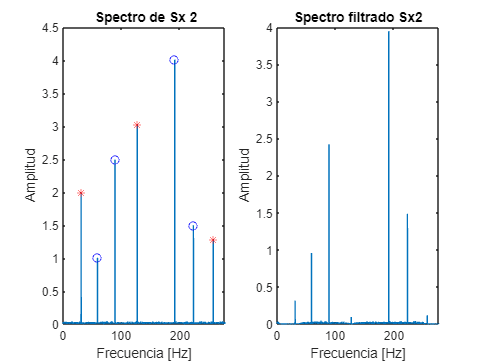

[fsx, tsxbut2]=fourier(sxbut2,fs);

%grafica
subplot(1,2,2);
plot(fsx, tsxbut2);
title("Spectro filtrado Sx2");
xlabel("Frecuencia [Hz]");
ylabel("Amplitud");
xlim([0 max(f0)+20]);


% caracterizacion para señal low
valor_maximo =max(tsxbut2) % valor maximo

valor_maximo = 3.9426

valor_promedio = mean(tsxbut2) % valor promedio

valor_promedio = 0.0136

desviacion_stadar = std(tsxbut2) % desviacion estandar

desviacion_stadar = 0.0693

varianza = var(tsxbut2) % varianza de la señal

varianza = 0.0048

correlacion=corrcoef([sx;sxbut2]')

correlacion =     1.0000    0.6299
    0.6299    1.0000


## señal 3

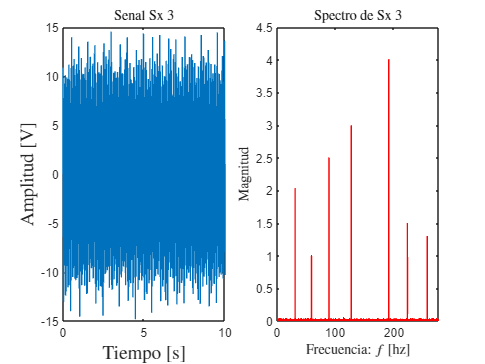

%señal
sx3 = sx3+(2*sin(w0(:,1).*t)+1*sin(w0(:,2).*t)+2.5*sin(w0(:,3).*t)...
            +3*sin(w0(:,4).*t)+4*sin(w0(:,5).*t)+1.5*sin(w0(:,6).*t)...
            +1.3*sin(w0(:,7).*t));
sx3=awgn(sx3,2);
%fourier
[tfsx3, fsx3] = tfourier(sx3,fs);

%grafica señal 3
figure;
subplot(1,2,1)
plot(t,sx3);
title(sprintf('Senal Sx 3'),"FontSize",10,'FontWeight',"bold","Interpreter","latex")
xlabel('Tiempo [s]', 'FontSize', 14, "FontWeight", "bold", "Interpreter", "latex");
ylabel('Amplitud [V]', 'FontSize', 14, "FontWeight", "bold", "Interpreter", "latex");
subplot(1,2,2)
set(gcf, 'Color', 'w');
plot(fsx3, tfsx3, 'r', 'LineWidth', 1.0);
title(sprintf('Spectro de Sx 3'),"FontSize",10,'FontWeight',"bold","Interpreter","latex")
xlabel('Frecuencia: $ f $ [hz]', 'FontSize', 10, 'FontWeight', 'bold', 'Interpreter', 'LaTex');
ylabel('Magnitud', 'FontSize', 10, 'FontWeight', 'bold', 'Interpreter', 'LaTex');
xlim([0 max(f0)+20]);


% identificacion de señal y artefacto
%señal
[pks11, locs11]=findpeaks1(tfsx3,[1.95 2.05],[2.45 2.55],[3.95 4.05],[1.25 1.35]);
%Artefactos
[pks12, locs12]=findpeaks(tfsx3,[0.95 1.05],[2.95 3.05],[1.45 1.55]);

%grafica de identificacion de señal y artefacto
figure;
subplot(1,2,1);
plot(fsx3,tfsx3);
hold on
plot(fsx3(locs12),pks12,'*r');
plot(fsx3(locs11),pks11,'ob');
title(" Spectro de Sx 3");
xlabel("Frecuencia [Hz]");
ylabel("Amplitud");
xlim([0 max(f0)+20]);

%Filtrado
tic
[sxbut3, time31]=fbutt(sx3,[45 63],fs,"stop",3);
toc

Elapsed time is 0.006694 seconds.


tic
[sxbut3, time32]=fbutt(sxbut3,[117 137],fs,"stop",1);
toc

Elapsed time is 0.011801 seconds.


tic
[sxbut3, time33]=fbutt(sxbut3,[210 243],fs,"stop",4);
toc

Elapsed time is 0.003095 seconds.


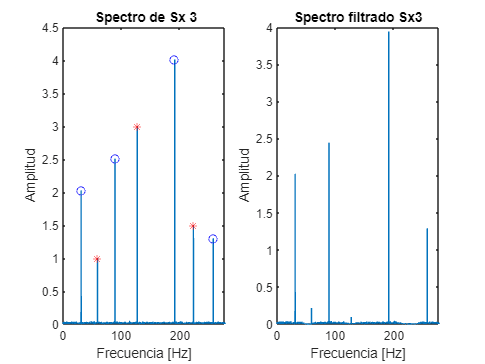

[fsx, tsxbut3]=fourier(sxbut3,fs);

%grafica
subplot(1,2,2);
plot(fsx, tsxbut3);
title("Spectro filtrado Sx3");
xlabel("Frecuencia [Hz]");
ylabel("Amplitud");
xlim([0 max(f0)+20]);


% caracterizacion para señal low
valor_maximo =max(tsxbut3) % valor maximo

valor_maximo = 3.9410

valor_promedio = mean(tsxbut3) % valor promedio

valor_promedio = 0.0143

desviacion_stadar = std(tsxbut3) % desviacion estandar

desviacion_stadar = 0.0729

varianza = var(tsxbut3) % varianza de la señal

varianza = 0.0053

correlacion=corrcoef([sx;sxbut3]')

correlacion =     1.0000    0.5507
    0.5507    1.0000


## funciones

% furier para señal original

function [signal,f] = tfourier(sig,Fs)
N = length(sig);
Xf = fft(sig);
Mag = abs(Xf/N);
signal = Mag(1:(N/2)+1);
signal(2:end-1) = 2*signal(2:end-1);
f = Fs*(0:(N/2))/N;
end
% fourier para filtro 
function [f,data] = fourier(x,fs)
    nsignals=length(x(:,1));
    for i=1:nsignals
        y=fft(x(i,:));
        z(i,:)=fftshift(y); 
        l=length(y);
        data(i,:)=2*abs(z(i,:)/l);%Señal fourier original        
    end    
    f=(-l/2:(l/2)-1)*fs/l;
end

% filtro butterworth
function [data,temp] = fbutt(x,fc,fs,tipo,n)
    tic
    [b,a] = butter(n,fc/(fs/2),tipo);
    data = filter(b,a,x);
    temp = toc;
end

% deteccion de picos en señal y artefacto 
function [pks,locs] = findpeaks(sig,rango1,rango2,rango3)
pks=[];
locs=[];
    for n=1:length(sig)
        if sig(n)>rango1(1) && sig(n)<rango1(2)
            pks=[pks,sig(n)];
            locs=[locs,n];
        end
        if sig(n)>rango2(1) && sig(n)<rango2(2)
            pks=[pks,sig(n)];
            locs=[locs,n];
        end
        if sig(n)>rango3(1) && sig(n)<rango3(2)
            pks=[pks,sig(n)];
            locs=[locs,n];
        end
    end
end

function [pks,locs] = findpeaks1(sig,rango1,rango2,rango3,rango4)
pks=[];
locs=[];
    for n=1:length(sig)
        if sig(n)>rango1(1) && sig(n)<rango1(2)
            pks=[pks,sig(n)];
            locs=[locs,n];
        end
        if sig(n)>rango2(1) && sig(n)<rango2(2)
            pks=[pks,sig(n)];
            locs=[locs,n];
        end
        if sig(n)>rango3(1) && sig(n)<rango3(2)
            pks=[pks,sig(n)];
            locs=[locs,n];
        end
        if sig(n)>rango4(1) && sig(n)<rango4(2)
            pks=[pks,sig(n)];
            locs=[locs,n];
        end
    end
end
